clc
clear all
close all

biodata_file=".dataset/DATA 22-25/Measurement 25042024/Rifa_Back33.txt"

biodata_file = ".dataset/DATA 22-25/Measurement 25042024/Rifa_Back33.txt"

table_raw = readtable(biodata_file);

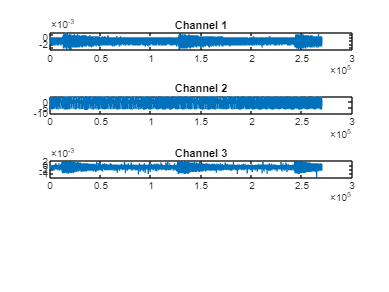

table_data = table_raw(2:end,:);

bio_t   = table_data(:,1);
bio_ch1 = table2array(table_data(:,2));
bio_ch2 = table2array(table_data(:,3));
bio_ch3 = table2array(table_data(:,4));
% bio_ch4 = str2double(strrep(table2array(table_data(:,6)),",",'.'));

%% Visualize Raw Bio-data
figure("Name","Bio Signal Visualize")
subplot(4,1,1)
plot(bio_ch1)
% xlim([10 20])
title('Channel 1');
subplot(4,1,2)
plot(bio_ch2)
% xlim([10 20])
title('Channel 2');
subplot(4,1,3)
plot(bio_ch3)
% xlim([10 20])
title('Channel 3');

% subplot(4,1,4)
% plot(bio_t,bio_ch4)
% xlim([10 20])
% title('Channel 4');